% Simulation Settings
xT  = [1;1;deg2rad(90)];   % Terminal Condition
m   = 0;                    % GENEX Design Parameter
V   = 1;                    % Velocity

% For Parallel Shooting (free time):
% - T = 0
% - Tmax = maximum final time
% - Delta = sampling rate  

T=0;
Tmax= 3;
delta = 0.1;
tic
sol1 = IndirectShootingP(xT,m,T,Tmax,V,delta)

sol1 = struct with fields:
        x: [57×7 double]
        u: [0.6113 0.6114 0.6114 0.6115 0.6115 0.6119 0.6122 0.6125 0.6128 0.6143 0.6159 0.6175 0.6190 0.6268 0.6345 0.6422 0.6498 0.6876 0.7245 0.7604 0.7954 0.8383 0.8794 0.9184 0.9553 0.9899 1.0220 1.0515 1.0784 1.1024 1.1235 1.1415 1.1565 1.1683 … ]
        J: [57×1 double]
     Cost: 1.5906
        T: 1.6000
    Tvals: [57×1 double]


toc

Elapsed time is 0.378520 seconds.


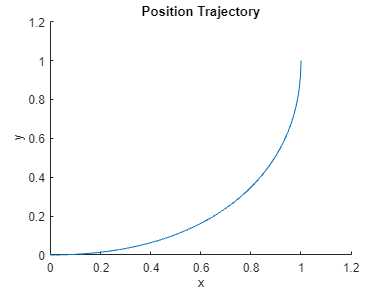


% For Normal Shooting (fixed time):
% - T = desired final time
% - Tmax = anything (value needs to be set but is not used) 
% - Delta = anything (value needs to be set but is not used)  

% T=2;
% Tmax = 0;
% delta = 0;
% tic
% sol2 = IndirectShootingP(xT,m,T,Tmax,V,delta)
% toc

% Plotting the Comparions
figure
hold on;
title('Position Trajectory')
plot(sol1.x(:,1),sol1.x(:,2));
%plot(sol2.x(:,1),sol2.x(:,2),'--')
%legend('Free Time', 'Fixed Time');
xlabel('x');
ylabel('y');
hold off;

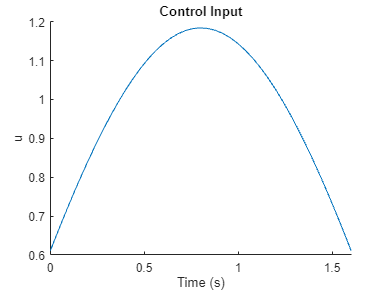


figure
hold on;
title('Control Input')
plot(sol1.Tvals,sol1.u)
%plot(sol2.Tvals,sol2.u,'--')
xlabel('Time (s)');
ylabel('u');
%legend('Free Time', 'Fixed Time');
hold off;